# Analysis 1

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C229_Data\';

%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

conditions = {
    'siCtrl DMSO',2,2:5,1:32,'siCtrl','DMSO'; 
    'siCtrl MLN',2,[6 7 8 10],1:32,'siCtrl','MLN';
    
    'siP27 DMSO',3,2:5,1:32,'siP27','DMSO'; 
    'siP27 MLN',3,6:10,1:32,'siP27','MLN';
    
    'siGMNN DMSO',4,2:5,1:32,'siGMNN','DMSO'; 
    'siGMNN MLN',4,6:10,1:32,'siGMNN','MLN';   

    'siP27/GMNN DMSO',5,2:5,1:32,'siP27/GMNN','DMSO'; 
    'siP27/GMNN MLN',5,6:10,1:32,'siP27/GMNN','MLN';   
    
    'siCtrl NR',6,2:5,1:32,'siCtrl','NR'; 
    'siP27 NR',7,6:10,1:32,'siP27','NR';      
};

S = loadData_IF(conditions, dataDir);

% save('E1090_data.mat','S');
colors =  [0    0.4470    0.7410;
    0.8500    0.3250    0.0980;
    0.9290    0.6940    0.1250;
    0.4940    0.1840    0.5560;
    0.4660    0.6740    0.1880;
    0.3010    0.7450    0.9330;
    0.6350    0.0780    0.1840];

## p27 vs APC for different conditions

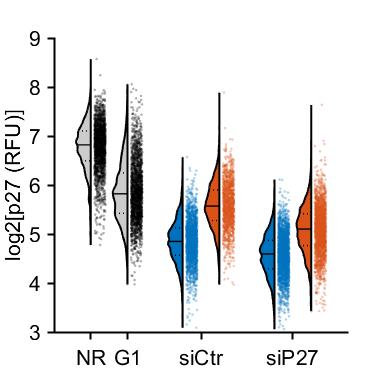

rng(1)

%conds = [1:4];
cond_g1 = [9 1 ];
cond_S = [1 2 3 4];
yval = 'YFP1';
ally = [];
group= [];
gind = 1;
%G1 
conds=cond_g1;
gateVals = {'dna','CDK4','normGem','CDK2','FarRed1','YFP1'};
rangeVals = {[2^20 2^21.5],[0 Inf],[0 .05],[.0 .8],[0 2^6],[2^3 2^9]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  real(log2(S(condition).(yval)));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ydata = randsample(ydata,2000);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end

%S phase
conds=cond_S;
gateVals = {'dna','CDK4','normGem','CDK2','YFP1'};
rangeVals = {[2^20 2^21.5],[0 Inf],[.25 .35],[.8 Inf],[2^3 2^9]}; 
for i=1:length(conds)
        
    condition=conds(i);
    ydata =  real(log2(S(condition).(yval)));
    totalGate =  gate_vals(S(condition), gateVals, rangeVals);   
    ydata = ydata(totalGate);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end
% group_list = 1:max(group)+1;
% offsetx = floor((group_list - 1)/2) * .5;
% xkey = group_list(1:end-1) + offsetx(2:end);
groups = 1:max(group);
offsetx = floor((groups - 1)/2) * .5;
xkey = groups + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames',{'G1','siCtrl S DMSO','siCtrl S MLN','siCdt1 S MLN','siCdt1 S MLN'},'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [[0 0 0];[0 0 0];cols([1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('log2[p27 (RFU)]')
xticks([1 2 xkey(3:2:length(xkey)-1)+.5])
xticklabels({'NR','G1','siCtr','siP27'})
ylim([3 9])
% hline(8)
% ylim([0 2.25])
% xtickangle(45)
axis square
print_pdf([pwd() '\Figs\p27_scatter.pdf'])

splitapply(@length,ally,group)

ans =         2000
        2000
        2043
        1396
        2376
        2110


conds = [1:8];

gateVals = {'dna','CDK2','CDK4','normGem','FarRed1'};
rangeVals = {[2^20 2^21.5],[.8 100],[0 100],[.25 .35],[2^0 Inf]}; 

ydata_all = [];
well_all = [];
cond_num_all = [];
cond_name_all = [];
drug_all = [];
sirna_all = [];
stain_all = [];
gem_all = [];
for j = 1:length(conds)
    condition = conds(j);
    ydata =  S(condition).FarRed1;
    well = S(condition).well_ID;
    staindata = S(condition).YFP1;
    gemdata = S(condition).YFP2;
    totalGate = true(size(ydata,1),1);
    
    for gate = 1:length(gateVals)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    well = well(totalGate);
    cond_num = repmat(condition,size(ydata));
    cond_name = repmat(string(conditions(condition,1)),size(ydata));
    drug = repmat(string(conditions(condition,6)),size(ydata));
    sirna = repmat(string(conditions(condition,5)),size(ydata));
    staindata = staindata(totalGate); 
    gemdata = gemdata(totalGate);
    
    ydata_all = [ydata_all; ydata];
    well_all = [well_all; string(well)];
    cond_num_all = [cond_num_all; cond_num];
    cond_name_all = [cond_name_all; cond_name];
    sirna_all = [sirna_all; sirna];
    drug_all = [drug_all; drug];
    stain_all = [stain_all; staindata];
    gem_all = [gem_all; gemdata];
end

df = table(categorical(cond_name_all),cond_num_all,categorical(well_all),categorical(sirna_all),categorical(drug_all),ydata_all, stain_all,gem_all);
df.Properties.VariableNames = {'cond','c_ind','well','sirna','drug','edu','stain','gem'};

wellsize = wellsize(:,:,1) =

   565   367
   732   495
   162   126
   254   140


wellsize(:,:,2) =

   493   357
   608   405
   145   120
   150    93


wellsize(:,:,3) =

   502   302
   543   337
   135    73
   153    92


wellsize(:,:,4) =

   484   371
   497   458
   149    77
   144    91


wellsize(:,:,5) =

   NaN   NaN
   NaN   418
   NaN    86
   NaN   113


ans = 73

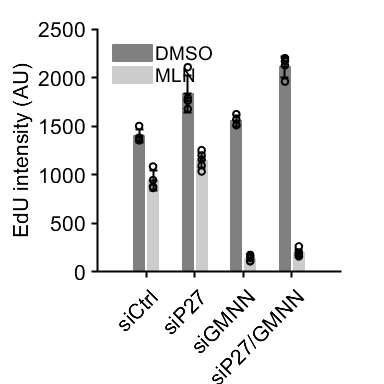

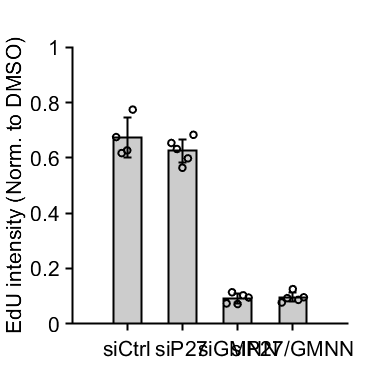

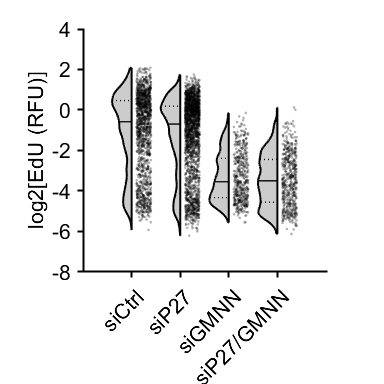

ans =         1397
        2113
         482
         529


h =    NaN     0     1     1
     0   NaN     1     1
     1     1   NaN     0
     1     1     0   NaN


p =        NaN    0.2351    0.0005    0.0008
    0.2351       NaN    0.0000    0.0000
    0.0005    0.0000       NaN    0.7778
    0.0008    0.0000    0.7778       NaN


colors = {[.5 .5 .5], [.8 .8 .8]};

sirnas = {'siCtrl','siP27','siGMNN','siP27/GMNN'};
drugs = {'DMSO','MLN'};
% stain_threshs = [Inf 2^8.5 2^8 2^8];
stain_threshs = [Inf  Inf Inf Inf  ];
gem_threshs = [Inf  Inf 2^7 2^7 ];

[h,p] = plot_groups(df, colors, drugs, stain_threshs, gem_threshs,sirnas,'all',false)

function [h,p]=plot_groups(df, colors, drugs, stain_threshs, gem_threshs, sirnas, name, ind_compare)
temp = rowfun(@(v) numel(unique(v)), df, 'GroupingVariables','c_ind','InputVariables','well');
maxwells = max(temp.Var3);
wellmeans = NaN * ones(length(sirnas),length(drugs),maxwells);
wellmedians = NaN * ones(length(sirnas),length(drugs),maxwells);
wellsize= NaN * ones(length(sirnas),length(drugs),maxwells);

means =  NaN * ones(length(sirnas),length(drugs));
sems =  NaN * ones(length(sirnas),length(drugs));

all_data = {};
for s = 1:length(sirnas)
    for d = 1:length(drugs)
        subdf = df(df.sirna == sirnas{s} & df.drug == drugs{d}, :);
        subdf = subdf(subdf.stain < stain_threshs(s) & subdf.gem < gem_threshs(s),:);
        data = subdf.edu;
        wells = subdf.well;
        groups = findgroups(wells);
        
        means(s,d) = mean(data);
        sems(s,d) = std(data)/sqrt(length(data));
        numwells = length(unique(groups));
        
        wellmeans(s,d,1:numwells) = splitapply(@mean, data, groups);  
        wellmedians(s,d,1:numwells) = splitapply(@median, data, groups);
        wellsize(s,d,1:numwells) = splitapply(@length, data, groups);
        
        all_data{s,d} = log2(data);
        
    end
end 

wellmeanmean = nanmean(wellmeans,3);
wellmeansem = nanstd(wellmeans,[],3)./sqrt(sum(~isnan(wellmeans),3));

wellmedmean = nanmean(wellmedians,3);
wellmedsem = nanstd(wellmedians,[],3)./sqrt(sum(~isnan(wellmeans),3));

norm_wellmedians = wellmedians ./ wellmedmean(:,1);
norm_wellmedmean = nanmean(norm_wellmedians,3);
norm_wellmedsem = nanstd(norm_wellmedians,[],3)./sqrt(sum(~isnan(norm_wellmedians),3));
wellsize
min(wellsize(:))

figure('units','inches','position',[0 0 4 4])
hBar = bar(1:length(sirnas), wellmedmean);
box off
axis square
offsets = [hBar.XOffset];
set(gca,'XTickLabel',sirnas);
xtickangle(45);
xlim([0 length(sirnas)+1])
cent = [];
for k1 = 1:size(wellmedmean,2)
    cent(:,k1) = hBar(k1).XData + offsets(k1);
    hBar(k1).FaceColor = colors{k1};
    hBar(k1).EdgeColor= colors{k1};    
end
cent_rep = repmat(cent,1,1,size(wellmedians,3));
hold on
errorbar(cent', wellmedmean', 2*wellmedsem', '+k','LineWidth',1.5)

scatter(cent_rep(:),wellmedians(:),25,'k','LineWidth',1.5)
hold off
legend(drugs,'Box','off','Location',"northwest")
ylabel('EdU intensity (AU)');
% % print_pdf([pwd() '\Figs\compare_' name '.pdf'])

h = [];
p = [];
if ind_compare
    si_compare1 = [1 1 1];
    drug_compare1 = [1 1 2];
    si_compare2 = [1 2 2];
    drug_compare2 = [2 1 2];
    
    for c = 1:length(si_compare1)
        [h(c), p(c)] = ttest(wellmedians(si_compare1(c),drug_compare1(c),:),wellmedians(si_compare2(c),drug_compare2(c),:),'Alpha',0.05,'Tail','both');
    end
    h
    p
end

figure('units','inches','position',[0 0 4 4])
hBar = bar(1:length(sirnas), norm_wellmedmean(:,2),.5,'FaceColor',colors{2},'EdgeColor','k','LineWidth',1.5);
box off
axis square

offsets = [hBar.XOffset];
set(gca,'XTickLabel',sirnas);
% xtickangle(45);
xlim([0 length(sirnas)+1])
ylim([0 1])
xvals = [1:length(sirnas)]';
yvals = squeeze(norm_wellmedians(:,2,:));
xval_rep = repmat(xvals,1,size(yvals,2));
hold on
errorbar(1:length(sirnas), norm_wellmedmean(:,2)', 2*norm_wellmedsem(:,2)', '+k','LineWidth',1.5)
jit = .2*linspace(-1,1,size(yvals,2));
xval_rep_jit = xval_rep + jit;
scatter(xval_rep_jit(:),yvals(:),25,'k','LineWidth',1.5)
hold off
ylabel('EdU intensity (Norm. to DMSO)');
print_pdf([pwd() '\Figs\comparenorm_' name '.pdf'])

% [p,t,stats] = anova1(yvals(:),xval_rep(:));
% c = multcompare(stats);
h = [];
p = [];
groups = unique(xval_rep);
for i = 1:length(groups)
    for j = 1:length(groups)
        x1 = yvals(xval_rep == groups(i));
        x2 = yvals(xval_rep == groups(j));
        [h(i,j), p(i,j)] = ttest(x1(:),x2(:),'Alpha',0.05,'Tail','both');
    end
end

## geminin vs APC for different conditions

cellmeds = cellfun(@median,all_data,'UniformOutput',false);
cellmeds(:,2) = cellmeds(:,1);
norm_data = cellfun(@(x,y) x-y, all_data,cellmeds,'UniformOutput',false);
norm_data = norm_data(:,2);
length_data = cellfun(@length,norm_data);
group_inds = (1:length(length_data))';
groups = arrayfun(@(x,y) repmat(x,y,1),group_inds,length_data,'UniformOutput',false);
group = cell2mat(groups);
ally = cell2mat(norm_data);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
ha = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],...
    'xNames',sirnas);
set(ha{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
% cols = lines(2);
% groupcol = [cols([1 2 1 2],:)];
% set(h{1},{'FaceColor'},{cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
% hold on
jit = 0.3*rand(size(group)) + .1;
% scatter(group'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
scatter(group+jit, (ally), 4,'filled','MarkerFaceColor','k','MarkerFaceAlpha',.3);
ylabel('log2[EdU (RFU)]')
% xticks([1 xkey(2:2:length(xkey)-1)+.5])
% xticklabels({'G1','S DMSO','S MLN'})
% hline(8.5,'k:')
% ylim([0 2.25])
xtickangle(45)
axis square
% print_pdf([pwd() '\Figs\gmnn_scatter.pdf'])

splitapply(@length,ally,group)
end